# Recocido Simulado

Encientra el valor minimo de la funcion (optimizar) usando la tecnica de optimizacion conocida como recocido simulado. La funcion es la siguiente: 

clear; 

## Definir parametros globales

N = 100;
limits = [-5 5];
f = @(x,y) -(1 + cos(12 .* sqrt(x.^2 + y.^2))) ./ (0.5 .* (x.^2 + y.^2) + 2) ; 
x = linspace(limits(1),limits(2),N);
y = linspace(-5,5,N);


## Visualizacion Inicial

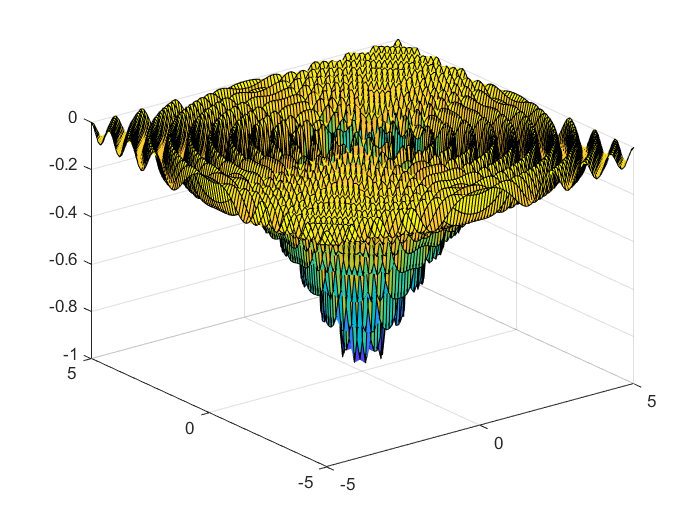

[X,Y] = meshgrid(x,y);
surf(x,y,f(X,Y))
hold on

## Recocido simulado (manual) 

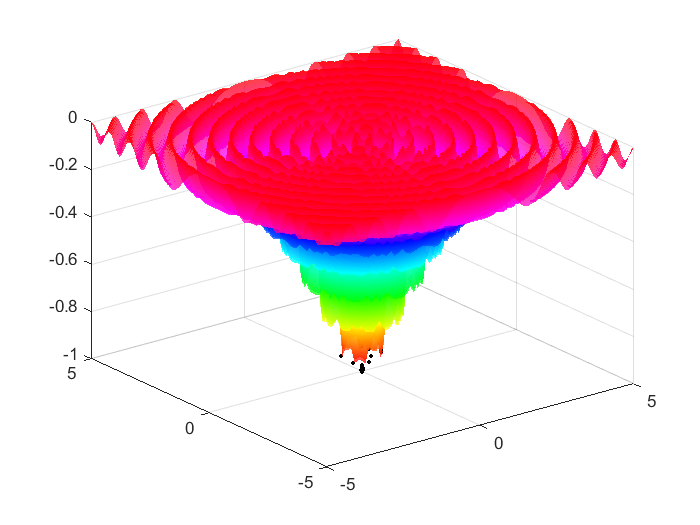

% Guess inicial
rng('shuffle');
pd1 = makedist('Uniform',limits(1),limits(2));

% Distribucion para los vecinos
dx = 0.5;
pd2 = makedist('Uniform',-dx,dx);

% Solucion inicial
Sol_act = random(pd1,1,2); %Two numbers

% Temperatura
T0 = -0.5 * f(Sol_act(1), Sol_act(2));
T = T0;

% alpha
alph = 0.9;

% Ciclos dentro del while
L = 1000;

% Temperatura final
Tf = 1E-15;

% Contador
cc = 1;

% axis equal
alpha 0.75
shading interp
colormap hsv
hold on

tic 
while T>Tf
    for ii = 1:L
        
        % Generamos vecinos
        Sol_cand = Sol_act + random(pd2,1,2);
        
        delta = f(Sol_cand(1),Sol_cand(2)) - ...
                f(Sol_act(1),Sol_act(2));
        
        % Generamos una x aleatoria (volado) y comparamos con Boltzman
        x = rand;
        Pboltz = exp(-delta/T);
        
        if x<Pboltz || delta<0
            Sol_act = Sol_cand;
        end 
    end
    
    % Almacenamos el minimo en un vector
    Cmin(cc) = f(Sol_act(1), Sol_act(2));
    
    % Enfriamos
    T = alph*T;
    Temp(cc) = T;

    cc = cc+1;
    
    % Visualizacion
    scatter3(Sol_act(1), Sol_act(2), f(Sol_act(1), Sol_act(2)), 50 ,'.' ,'black'),
    hold on
    %pause(0.01);
end

toc

Elapsed time is 8.965226 seconds.


Sol_act

Sol_act =     0.0012   -0.0022


f(Sol_act(1),Sol_act(2))

ans = -0.9998

hold off

## Recocido simulado (Toolbox)

x0 = random(pd1,1,2);
fun = @(x) f(x(1), x(2));
tic
[xy_toolbox , f_val] = simulannealbnd(fun, x0, [limits(1),limits(1)],[limits(2),limits(2)])

Optimization terminated: change in best function value less than options.FunctionTolerance.


xy_toolbox =     0.1303    0.5036


f_val = -0.9362

toc

Elapsed time is 1.505500 seconds.
